syms s 
s = tf('s');

%Load the linearizer .mat file
Linearizer_3 = load("Assignment_3_linearizer.mat");
%q1 is 1 = the OG plant/controller
%q2 is 2 = the high stiffness system
%q6 is 3/4/5 = 150k,100k, and 133k respectively
%q7 is 6 = optimal + lpf
q1 = Linearizer_3.LinearAnalysisToolProject.Results(1).Data.Value;
q2 = Linearizer_3.LinearAnalysisToolProject.Results(2).Data.Value;
q6_1_150 = Linearizer_3.LinearAnalysisToolProject.Results(3).Data.Value;
q6_2_100 = Linearizer_3.LinearAnalysisToolProject.Results(4).Data.Value;
q6_3_133 = Linearizer_3.LinearAnalysisToolProject.Results(5).Data.Value;
q7 = Linearizer_3.LinearAnalysisToolProject.Results(6).Data.Value;
%Load the linearizer .mat file from assignment 2 for Q2
Linearizer_a2 = load("Assignment_2_linearizer.mat");
q2_2 = Linearizer_a2.LinearAnalysisToolProject.Results(5).Data.Value;




%System Parameters
m_lens = 2e-4; %mass of the lens, kg
m_rcoil = 5e-4; %mass of radial coil, kg
m_fcoil = 3e-4; % mass of the focal coil, kg

m2 = m_lens+m_rcoil+m_fcoil; %mass of the total system, m1, kg
m1 = 100e-3; %mass of the frame, m2, kg

f_dist = 25; %natural frequency of the system that connects frame to the fixed world, Hz
w_dist = 2*pi*f_dist;
f_sys = 40; %natural frequency of the system that connects frame to the system, Hz
w_sys = 2*pi*f_sys;

%calculating stiffness between a)world and frame, and b)frame and system
k1 = (m1+m2)*(w_dist^2); %stiffness between world and the frame
k2 = m2*(w_sys^2); %stiffness between frame and system 

%damping and stiffness parameters of the system
z1 = 0.1;
c1 = 2*z1*sqrt(k1*(m1+m2));
z2 = 0.05;
c2 = 2*z2*sqrt(k2*m2);

z_fcoil = 0.005;
k_fcoil = 0.2e6; % stiffness in N/m
c_fcoil = 2*z_fcoil*sqrt(k_fcoil*m_fcoil); %is this correct? double check

z_lens = 0.005;
k_lens = 1e6; % stiffness in N/m
c_lens = 2*z_lens*sqrt(k_lens*m_lens); %is this correct? double check

%Rule of Thumb PID controller
f_bw = 800;
Kp = (2*pi*f_bw)^2 * m2; 

%calculating Td = 1/wd and Tt for derivative control
f_d = f_bw/3;
w_d = 2*pi*f_d;
T_d = 1/w_d;
f_t = f_bw*3;
w_t = 2*pi*f_t;
T_t = 1/w_t;

%Calculating w_i
f_i = f_bw/10;
w_i = 2*pi*f_i;
T_i = 1/w_i;


%Q2
k_fcoil = 0.2e15; % stiffness in N/m
c_fcoil = 2*z_fcoil*sqrt(k_fcoil*m_fcoil); 
k_lens = 1e15; % stiffness in N/m
c_lens = 2*z_lens*sqrt(k_lens*m_lens); 


%bode plot config
opts = bodeoptions("cstprefs");
opts.FreqUnits = ('Hz');
opts.MagUnits = ('abs');
opts.Grid = ('on');
opts.MagScale = ('log');


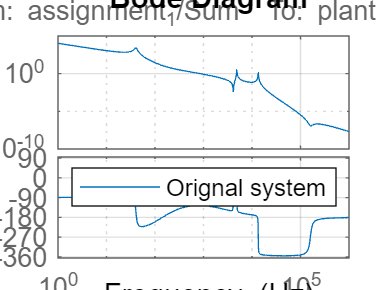

%Plotting the original system 
figure;
bode(q1, opts)
legend("Orignal system")

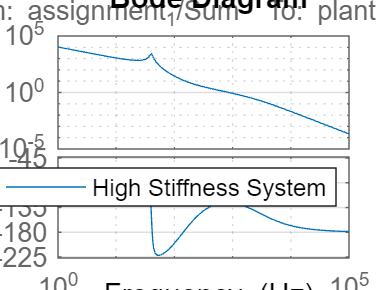

% Plotting system with very high stiffness
figure;
bode(q2, opts)
legend('High Stiffness System');

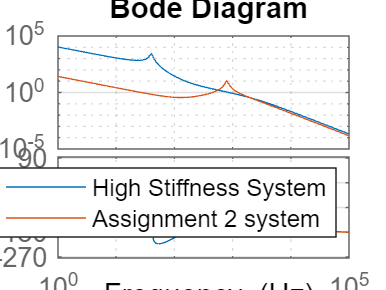

% Plotting system with very high stiffness compared to assigment 2
figure;
bode(q2,q2_2,opts)
legend('High Stiffness System','Assignment 2 system');

%Q3 This may be unneccessary. Just comment above?
k_fcoil = 0.2e6; % stiffness in N/m
c_fcoil = 2*z_fcoil*sqrt(k_fcoil*m_fcoil); 
k_lens = 1e6; % stiffness in N/m
c_lens = 2*z_lens*sqrt(k_lens*m_lens); 

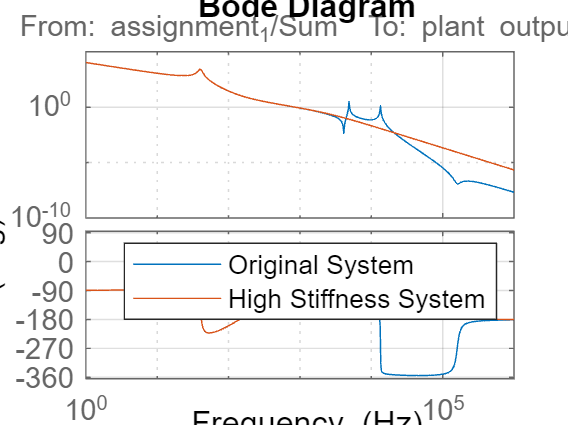

% Plotting system with very high stiffness and OG system together
figure;
bode(q1, q2, opts)
legend('Original System','High Stiffness System');

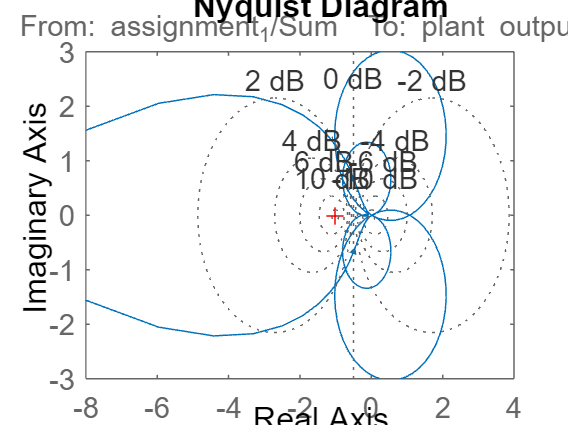

%plot the Nyquist plot
figure;
h1 = nyquistplot(q1);
setoptions(h1, 'ShowFullContour', 'on');
grid on;
xlim([-8 4]);
ylim([-3 3]);

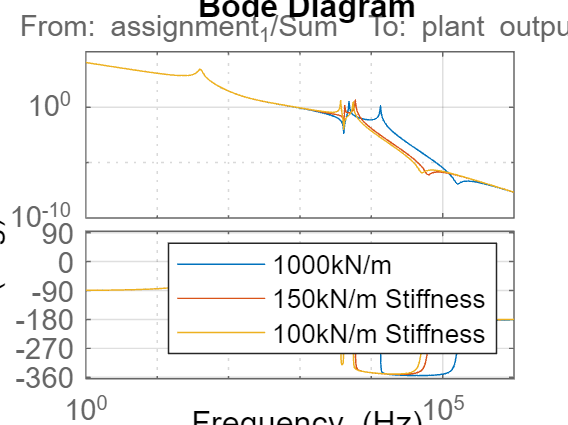

%Q6

%Define stiffness of 150k N/m
k_lens = 150e3; % stiffness in N/m
c_lens = 2*z_lens*sqrt(k_lens*m_lens);

%Define stiffness of 100k N/m
k_lens = 100e3; % stiffness in N/m
c_lens = 2*z_lens*sqrt(k_lens*m_lens); 

%Plotting comparison between 150k and 100k stiffness systems 
figure;
bode(q1,q6_1_150,q6_2_100, opts);
legend("1000kN/m",'150kN/m Stiffness', '100kN/m Stiffness');

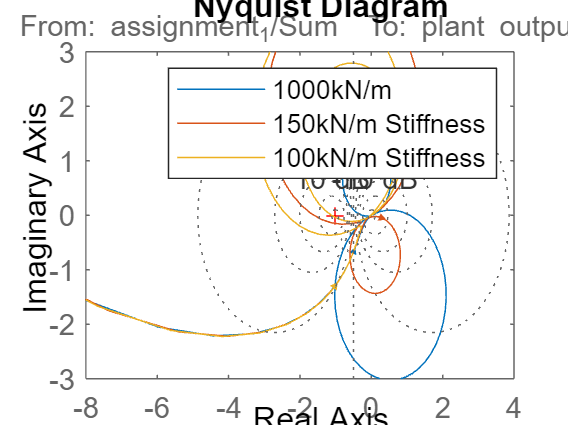


figure;
h2 = nyquistplot(q1,q6_1_150, q6_2_100);
setoptions(h2, 'ShowFullContour', 'off');
grid on;
xlim([-8 4]);
ylim([-3 3]);
legend("1000kN/m",'150kN/m Stiffness', '100kN/m Stiffness');

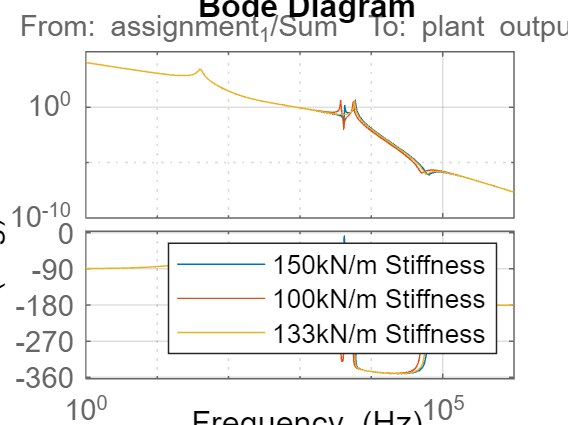

%Define optimal stiffness 
%Value found by getting close to zero phase change at the resonance
k_lens = 133.35e3; % stiffness in N/m
c_lens = 2*z_lens*sqrt(k_lens*m_lens); 

%Plotting comparison between 150k, 100k and 133k stiffness systems 
figure;
bode(q6_1_150, q6_2_100, q6_3_133, opts);
legend('150kN/m Stiffness', '100kN/m Stiffness', '133kN/m Stiffness');

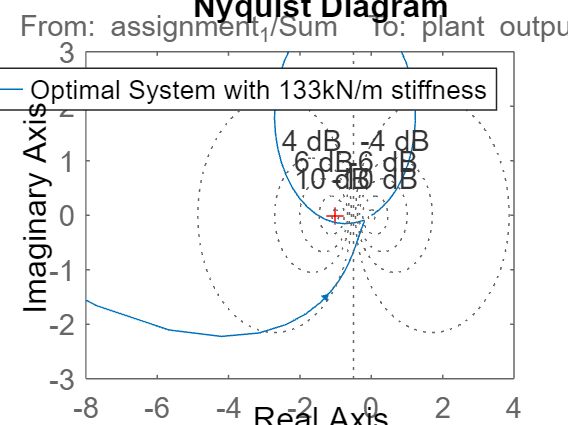


%Plot Nyquist for 133k system
figure;
h3 = nyquistplot(q6_3_133);
setoptions(h3, 'ShowFullContour', 'off');
grid on;
xlim([-8 4]);
ylim([-3 3]);
legend('Optimal System with 133kN/m stiffness');

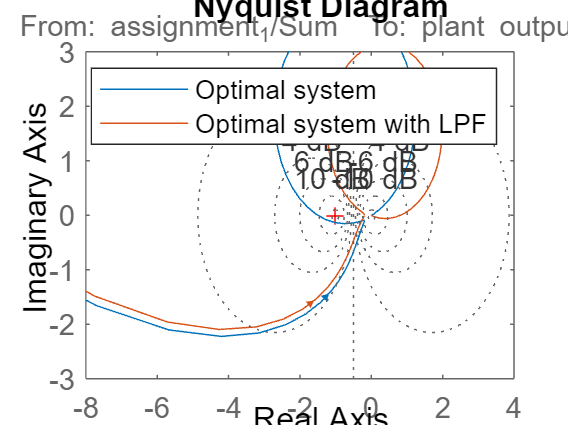

%Q7
%Add low pass filter?
%LPF, starting with f_bw*10 then try to shift up and down.
f_lpf = f_bw*10; 
w_lpf = 2*pi*f_lpf;
lpf = 1/(1+s/w_lpf);

%Plotting the effect of LPF
figure;
h4 = nyquistplot(q6_3_133,q7);
setoptions(h4, 'ShowFullContour', 'off');
grid on;
xlim([-8 4]);
ylim([-3 3]);
legend('Optimal system','Optimal system with LPF');

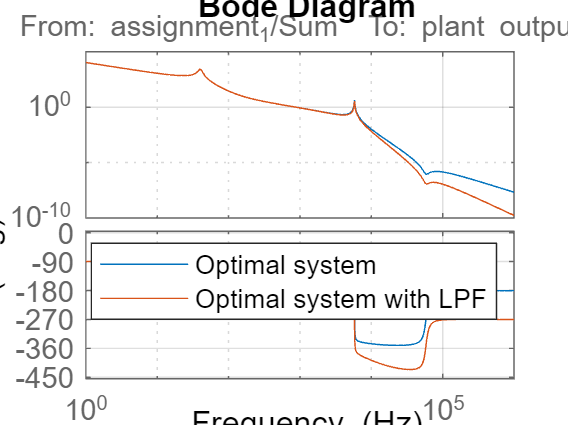


figure;
bode(q6_3_133, q7, opts);
legend('Optimal system','Optimal system with LPF');